# Compare Normalizations

clear variables
close all
format long

## Load data from matrices

dir='/Users/ana/Documents/Ana/universidade/Tese/Code/matlab_scripts/matrix_data';
dir_roi='/Users/ana/Documents/Ana/universidade/Tese/Code/matlab_scripts/roi_sizes';
atlas="AAL116";
threshold=0;
normalizations=[1 2 3 4];
[allconnectomes,n_conditions,n_people,node_labels,condition_names] = get_data(dir,dir_roi,atlas,threshold,normalizations,false);

clear threshold atlas dir dir_roi

## Scatter plot and correlation coefficients

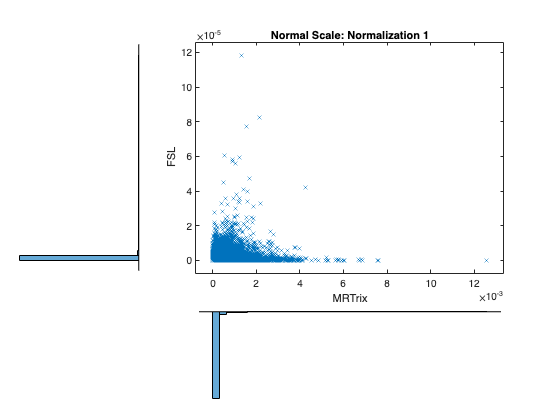

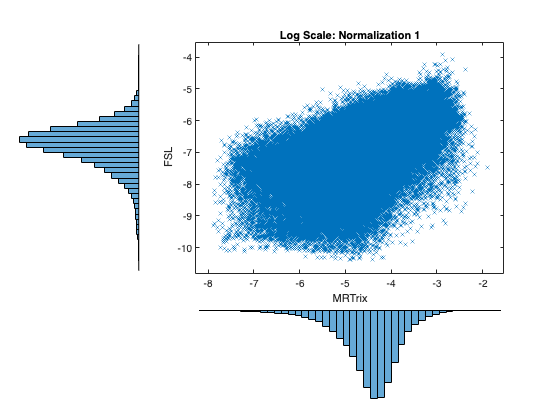

Normal Scale Pearson's correlation coefficient N1: 0.34391


Log Scale Pearson's correlation coefficient N1: 0.55719


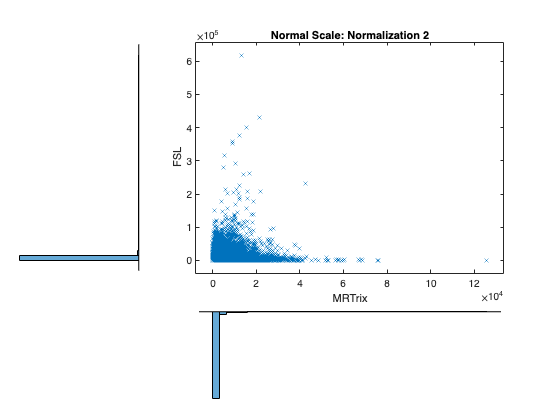

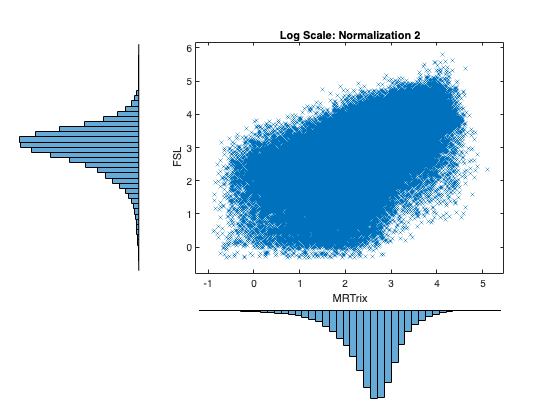

Normal Scale Pearson's correlation coefficient N2: 0.34582


Log Scale Pearson's correlation coefficient N2: 0.5647


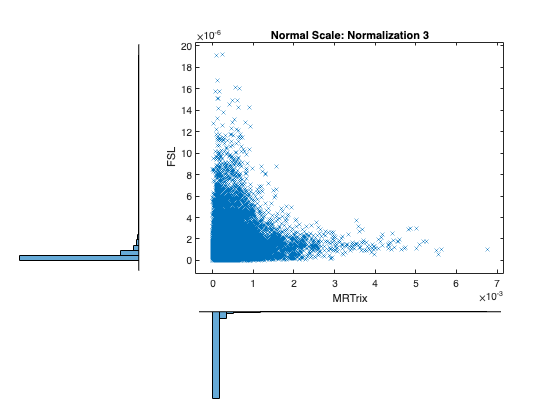

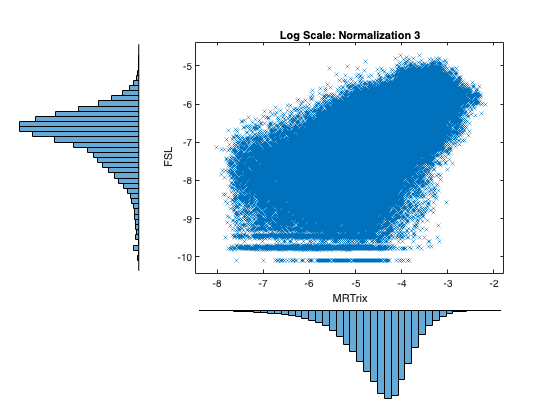

Normal Scale Pearson's correlation coefficient N3: 0.40454


Log Scale Pearson's correlation coefficient N3: 0.61888


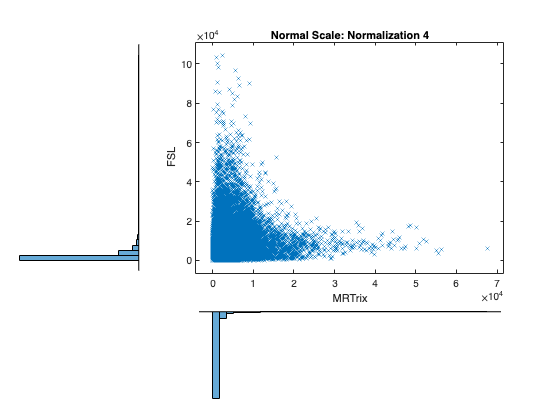

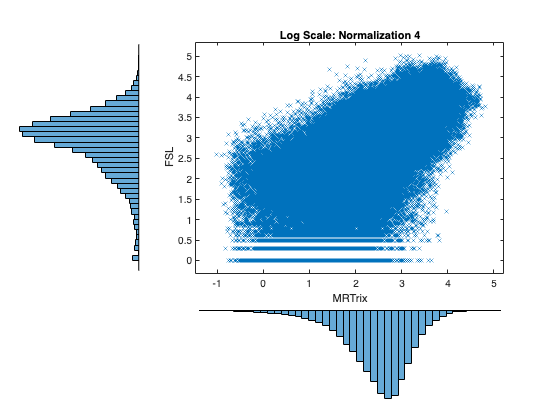

Normal Scale Pearson's correlation coefficient N4: 0.40363


Log Scale Pearson's correlation coefficient N4: 0.62631


nnodes=length(node_labels);
for con=1:length(allconnectomes)
    scatterv=[[],[]];
    scatterv=zeros((sum(n_people)/2)*((nnodes*nnodes-nnodes)/2),2);
    idx=1;
    connectomes=allconnectomes{con};
    for c=[1 2 5 6]%linspace(1,7,4)
        for p=1:n_people(c)
            for i=1:nnodes-1
                for j=i+1:nnodes
                    scatterv(idx,:)=[connectomes{c}(i,j,p) connectomes{c+2}(i,j,p)];
                    idx=idx+1;
                end
            end
        end
    end

    scattervlog=log10(scatterv);
    for i=length(scattervlog):-1:1
        if isinf(scattervlog(i,1)) || isinf(scattervlog(i,2))
            scattervlog(i,:)=[];
        end
    end

    figure('color','w')
    scatterhist(scatterv(:,1),scatterv(:,2), 'NBins',[40,40],'Direction','out',Marker='x');
    xlabel('MRTrix');ylabel('FSL')
    title("Normal Scale: Normalization "+num2str(con))


    figure('color','w')
    scatterhist(scattervlog(:,1),scattervlog(:,2), 'NBins',[40,40],'Direction','out',Marker='x');
    xlabel('MRTrix');ylabel('FSL')
    title("Log Scale: Normalization "+num2str(con))

    R= corr(scatterv,"Type","Pearson");
    disp("Normal Scale Pearson's correlation coefficient N"+num2str(con)+": "+ num2str(R(1,2)))
    Rlog= corr(scattervlog,"Type","Pearson");
    disp("Log Scale Pearson's correlation coefficient N"+num2str(con)+": "+ num2str(Rlog(1,2)))
end


clear i j p c R Rlog scatterv idx con

## Get metrics

allmetrics=cell(size(allconnectomes));
version_metrics=2;%  3=nodal metrics, 2=general metrics
load('allmetrics2.mat')

for i=1:length(allconnectomes)
    connectomes=allconnectomes{i};
    allmetrics{i}=get_metrics(connectomes,version_metrics);
end

calculating metrics: 100%    [..........]done
calculating metrics: 100%    [..........]done
calculating metrics: 100%    [..........]done
calculating metrics: 100%    [..........]done


metrics_labels=get_label_metrics(version_metrics,node_labels);

clear connectomes i version_metrics

## Make anova

L


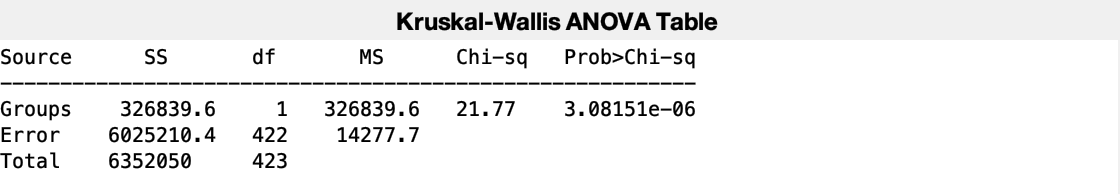

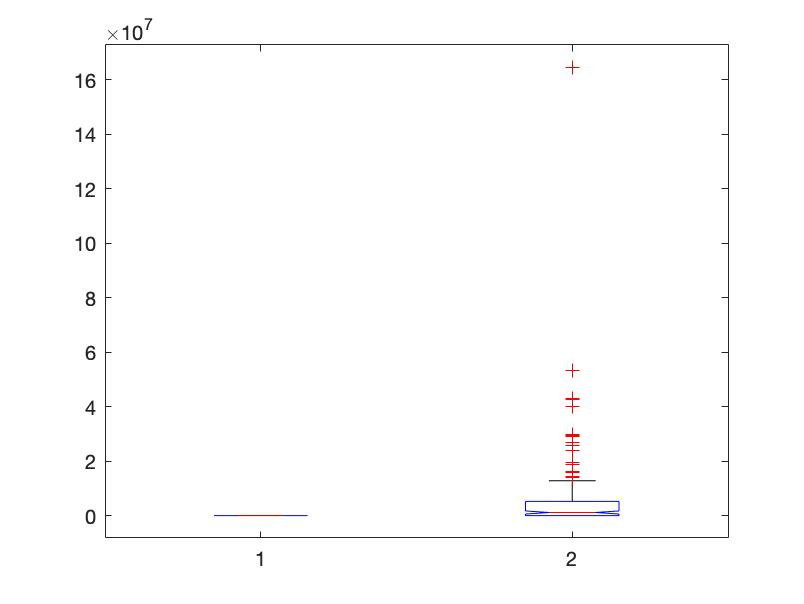

GE


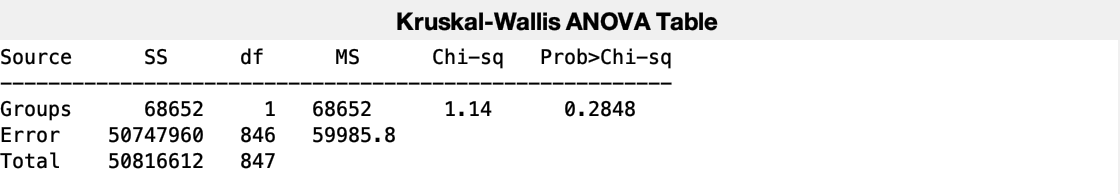

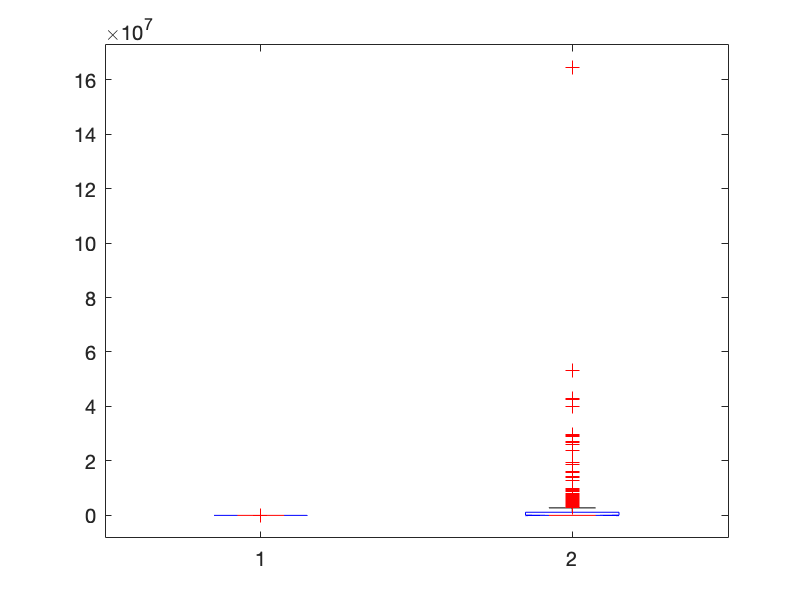

C


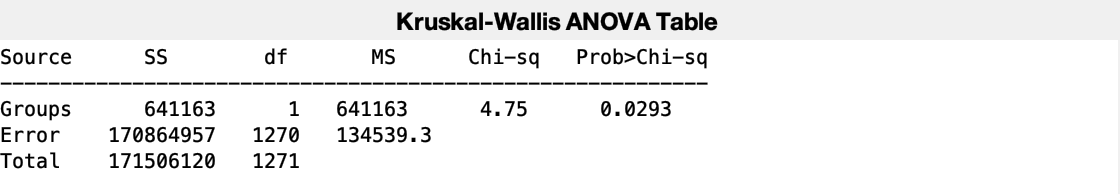

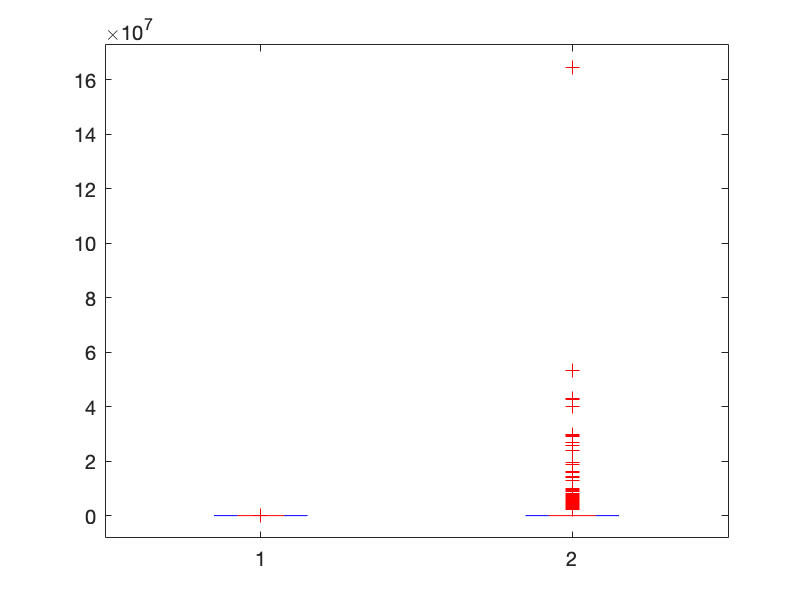

Q


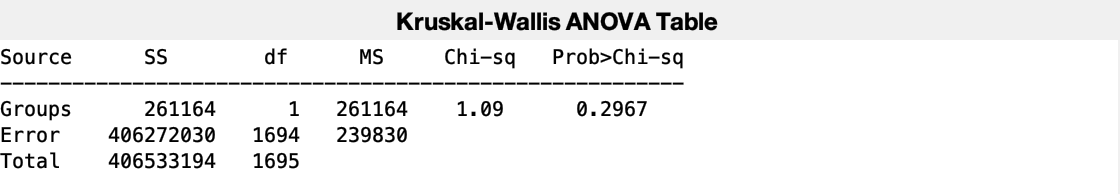

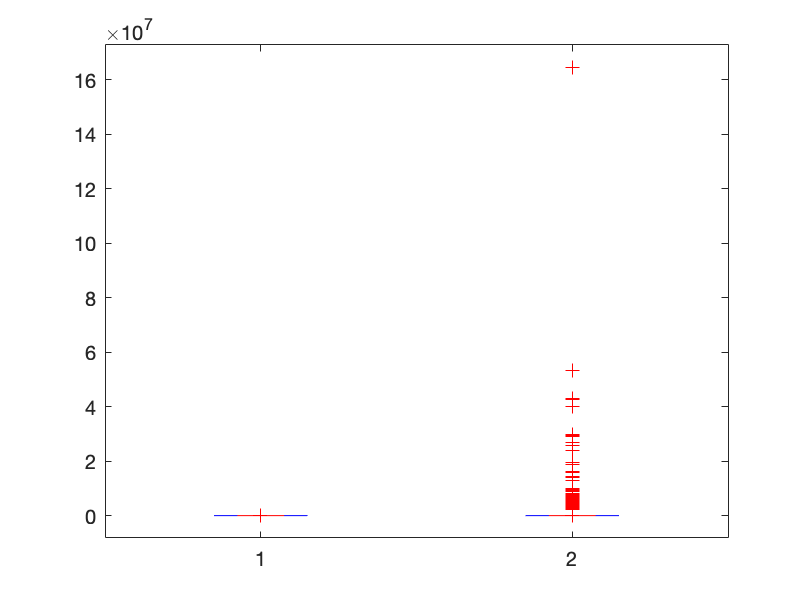

mean_D


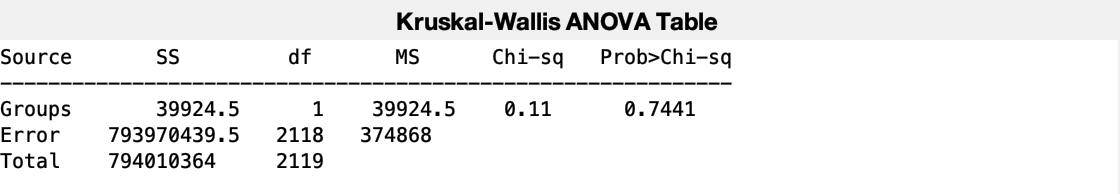

T


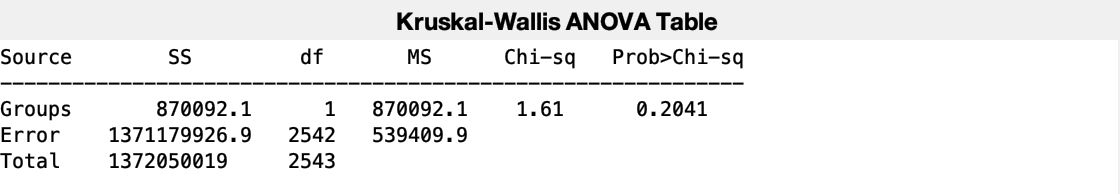

S


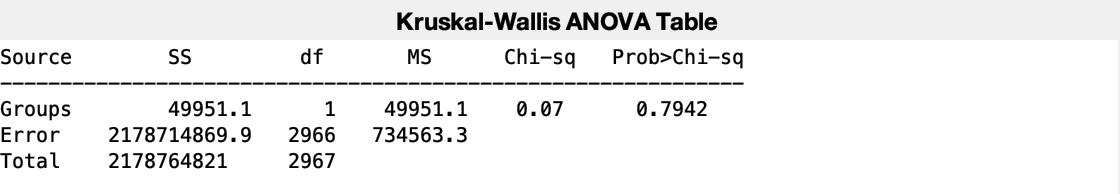

n_norms=length(allmetrics);

alg=[1 1 2 2 1 1 2 2];
cond=[1 2 1 2 3 4 3 4];
data=zeros(1,n_norms*sum(n_people));
g_alg=zeros(1,n_norms*sum(n_people));
g_norm=zeros(1,n_norms*sum(n_people));
g_cond=zeros(1,n_norms*sum(n_people));
i=1;
for metric=1:7 % for all metrics
    for norm=1:n_norms % for all normalizations
        metrics_norm=allmetrics{norm};
        for conds=1:numel(metrics_norm)% for all conditions
            metrics=cell2mat(metrics_norm(conds));
            for data_point=1:length(metrics(metric,:))
                data(i)=metrics(metric,data_point);
                g_alg(i)=alg(conds);
                g_norm(i)=norm;
                g_cond(i)=cond(conds);
                i=i+1;
            end
        end
    end
    disp(metrics_labels(metric))
    [p,tbl,stats] = kruskalwallis(data,g_alg);
end

L


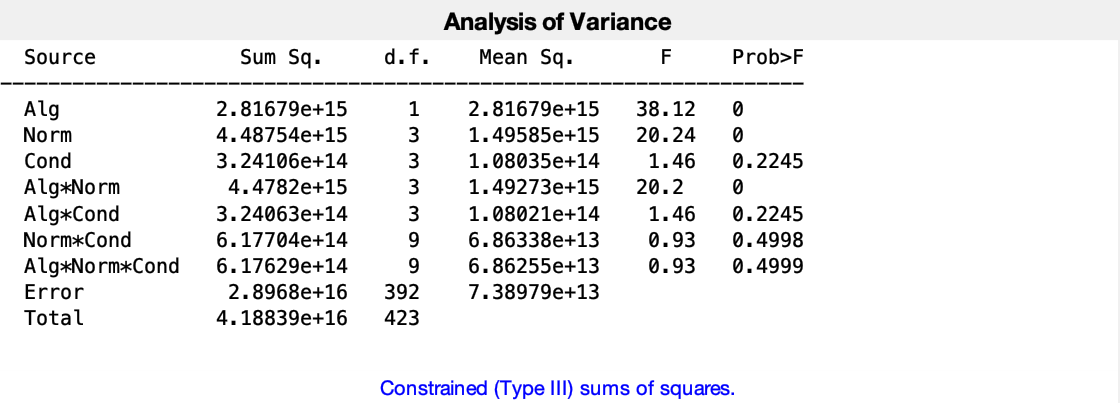

GE


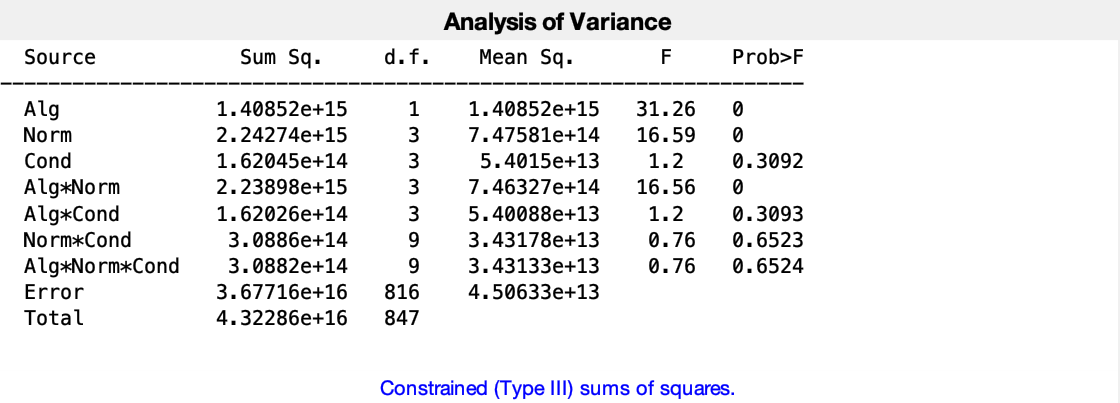

C


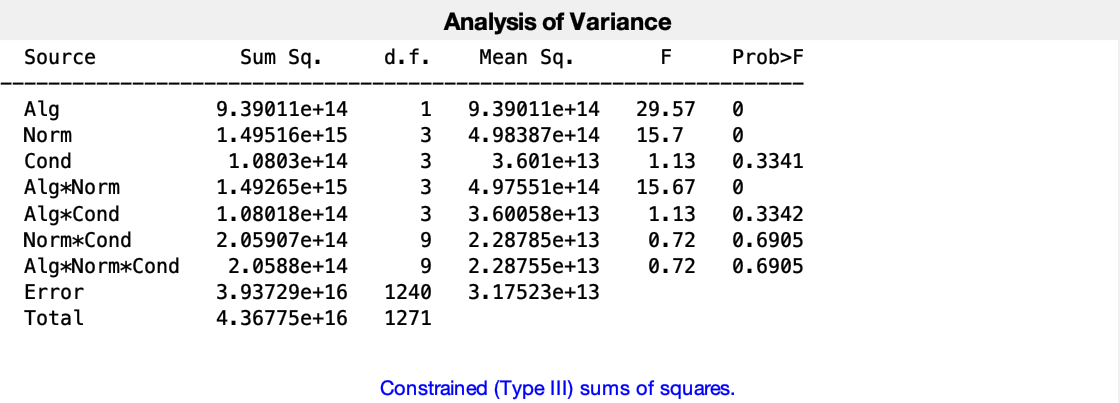

Q


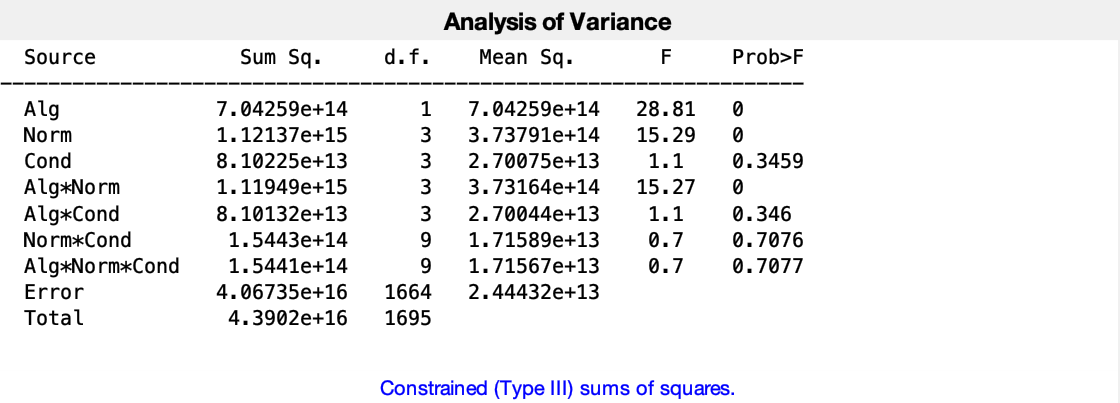

mean_D


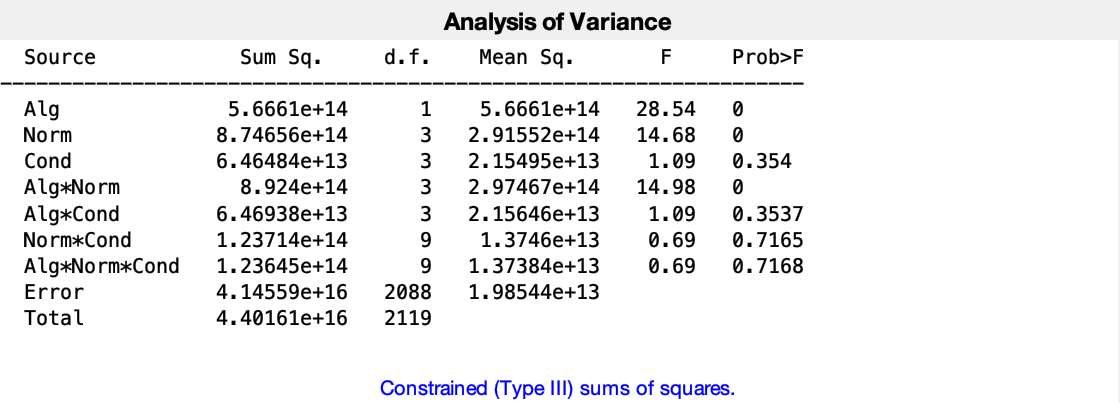

T


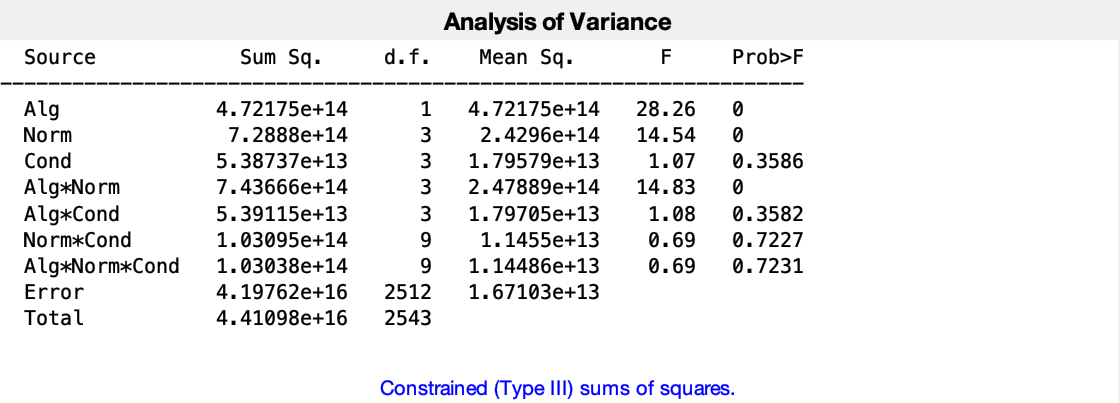

S


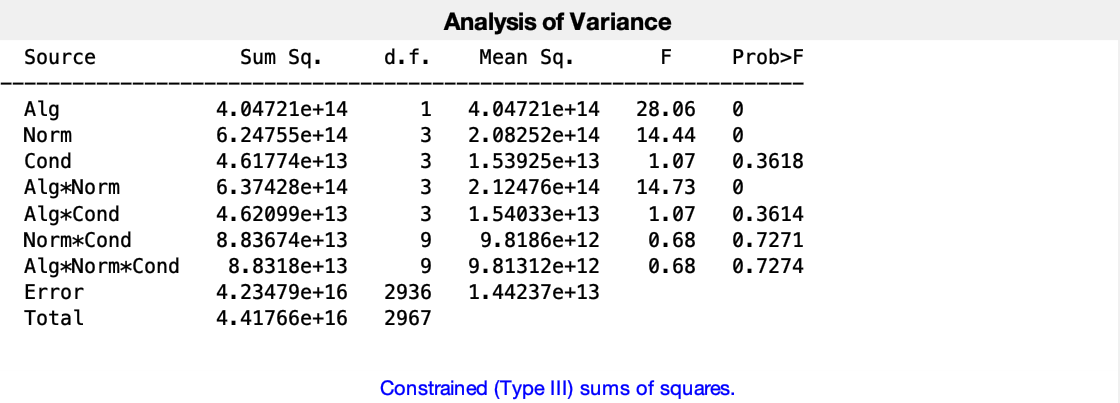

alg=[1 1 2 2 1 1 2 2];
cond=[1 2 1 2 3 4 3 4];

data=zeros(1,n_norms*sum(n_people));
g_alg=zeros(1,n_norms*sum(n_people));
g_norm=zeros(1,n_norms*sum(n_people));
g_cond=zeros(1,n_norms*sum(n_people));
i=1;
for metric=1:7 % for all metrics
    for norm=1:n_norms % for all normalizations
        metrics_norm=allmetrics{norm};
        for conds=1:numel(metrics_norm)% for all conditions
            metrics=cell2mat(metrics_norm(conds));
            for data_point=1:length(metrics(metric,:))
                data(i)=metrics(metric,data_point);
                g_alg(i)=alg(conds);
                g_norm(i)=norm;
                g_cond(i)=cond(conds);
                i=i+1;
            end
        end
    end
    disp(metrics_labels(metric))
    [p,tbl,stats,terms] = anovan(data,{g_alg,g_norm,g_cond},'model', 'full','varnames',{'Alg','Norm','Cond'});
    
end




% data=zeros(1,n_norms*sum(n_people));
% g_alg=zeros(1,n_norms*sum(n_people));
% g_norm=zeros(1,n_norms*sum(n_people));
% g_cond=zeros(1,n_norms*sum(n_people));
% g_cycle=zeros(1,n_norms*sum(n_people));
% i=1;
% for metric=1:7 % for all metrics
%     for norm=1:n_norms % for all normalizations
%         metrics_norm=allmetrics{norm};
%         for conds=1:numel(metrics_norm)% for all conditions
%             metrics=cell2mat(metrics_norm(conds));
%             for data_point=1:length(metrics(metric,:))
%                 data(i)=metrics(metric,data_point);
%                 g_alg(i)=alg(conds);
%                 g_norm(i)=norm;
%                 g_cond(i)=cond(conds);
%                 g_cycle(i)=cycle(conds);
%                 i=i+1;
%             end
%         end
%     end
%     disp(metrics_labels(metric))
%     [p,tbl,stats,terms] = anovan(data,{g_alg,g_norm,g_cond,g_cycle},'nested',[0 0 0 0;0 0 0 0;0 0 0 0;0 0 1 0],'model', 'full','varnames',{'Alg','Norm','Cond','Cycle'});
% end





clear i data_point conds norm metric metrics_norm metrics alg cond

## Plot Boxchart (color=algorithm)

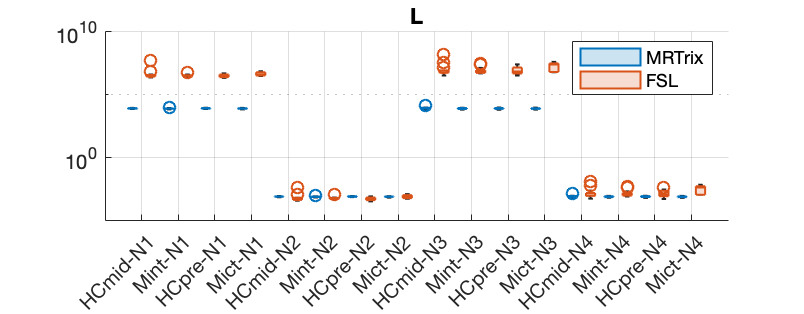

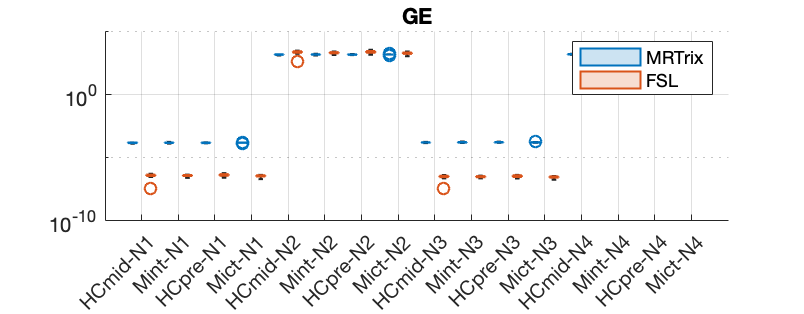

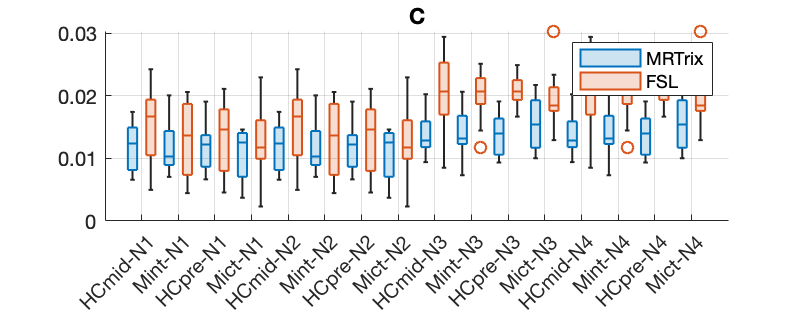

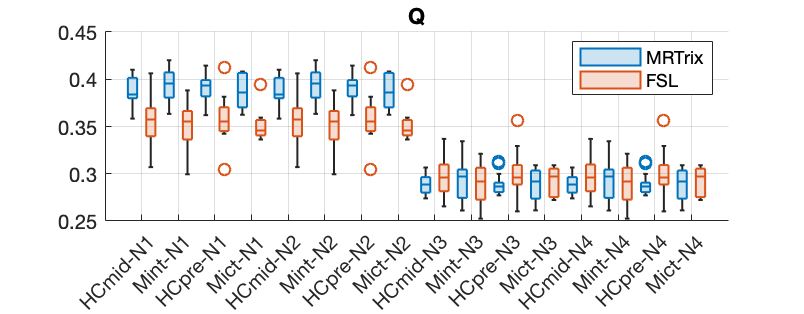

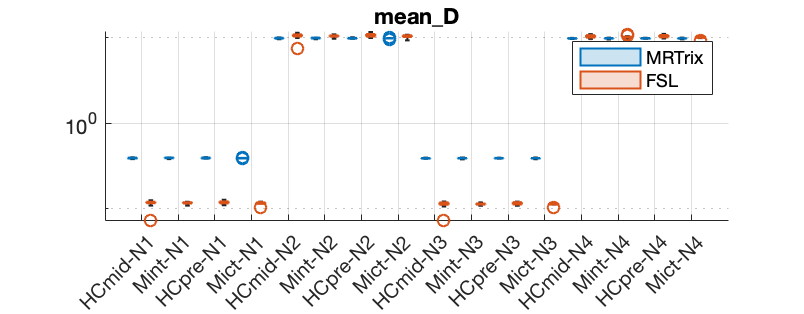

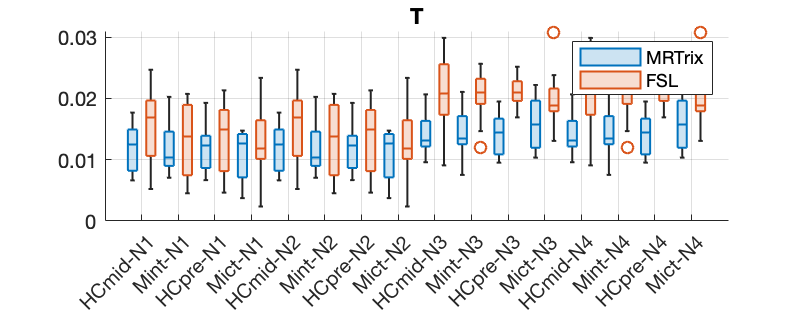

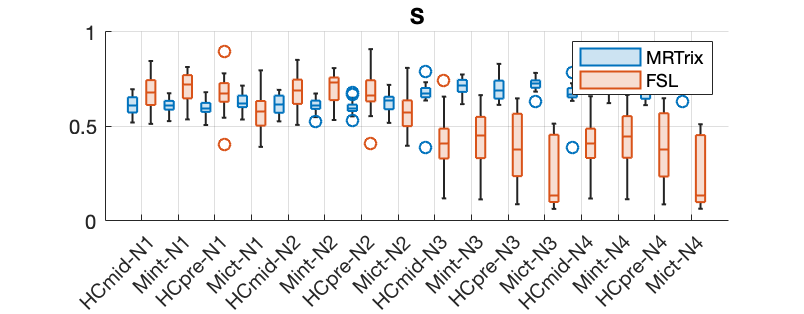

notlog=[3 4 6 7];

groups_color=[1 1 2 2 1 1 2 2];


for metric=1:7
    clear data;i=1;
    for norm=1:length(normalizations)
        metrics=allmetrics{norm};
        for c=1:n_conditions
            data{i,:}=metrics{c}(metric,:);
            i=i+1;
        end
    end
    data=data';
    positionaldata=[];
    colordata=[];
    groups_position=[1 2 1 2 3 4 3 4 5 6 5 6 7 8 7 8 9 10 9 10 11 12 11 12 13 14 13 14 15 16 15 16];
    groups_color=repmat(groups_color,[1 length(normalizations)]);


    for i=1:length(data)
        positionaldata=[positionaldata groups_position(i)*ones(1,length(data{i}))];
        colordata=[colordata groups_color(i)*ones(1,length(data{i}))];

    end

    %     disp(metrics_labels(metric))
    %     for i=1:length(data)-1
    %         for j=i+1:length(data)
    %             p=stattest(data{i},data{j});
    %             if p<0.05/(16*15)
    %                 disp(num2str(i)+"-"+num2str(j)+": p="+num2str(p))
    %             end
    %         end
    %     end

    data=cell2mat(data);
    colorlabels={'MRTrix' 'FSL'};
    xlabels={'HCmid-N1' 'Mint-N1' 'HCpre-N1' 'Mict-N1' ...
        'HCmid-N2' 'Mint-N2' 'HCpre-N2' 'Mict-N2'...
        'HCmid-N3' 'Mint-N3' 'HCpre-N3' 'Mict-N3'...
        'HCmid-N4' 'Mint-N4' 'HCpre-N4' 'Mict-N4'};
    positionaldata=discretize(positionaldata,1:17,'categorical',xlabels);

    figure('color','w','units','normalized','Position',[0.2,0.2,0.8,0.5])
    boxchart(positionaldata,data,'GroupByColor',colordata);
    if ~ismember(metric,notlog)
        set(gca, 'YScale', 'log');
    end
    grid on
    legend(colorlabels)
    title(metrics_labels(metric),'interpreter', 'none')
end


clear notlog positionaldata xlabels colorlabels data colordata groups_color groups_position i c metric norm


## Plot Boxchart (color=condition)

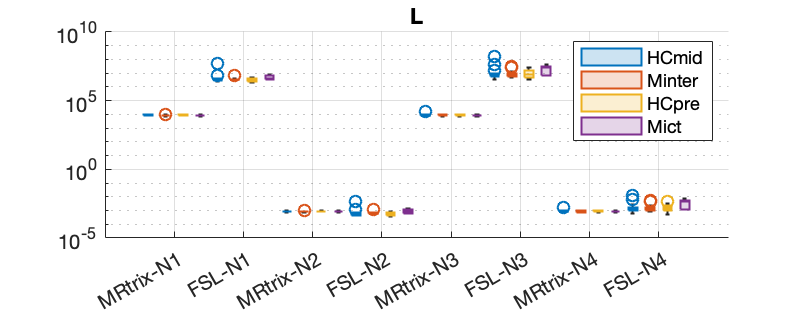

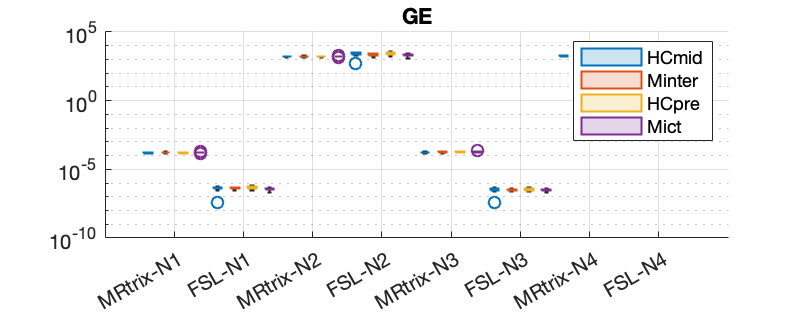

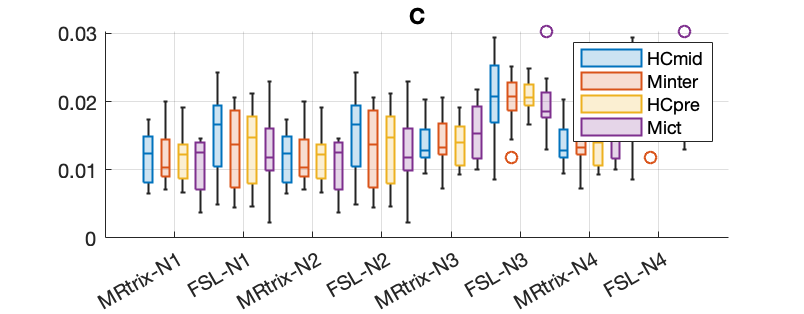

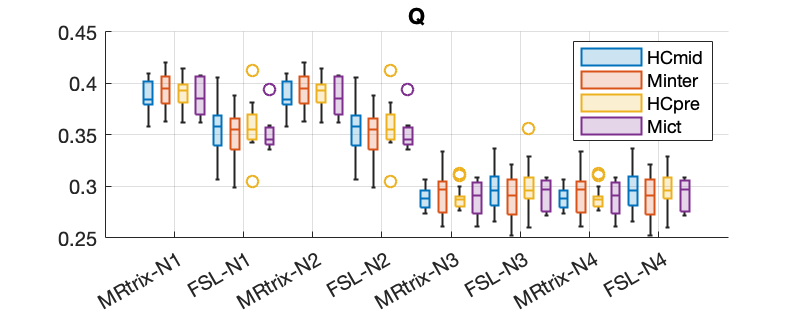

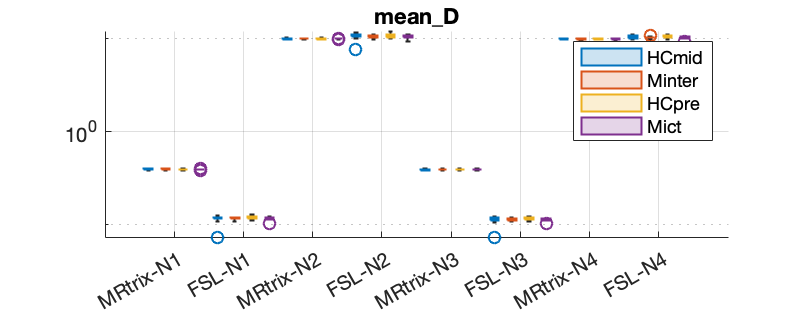

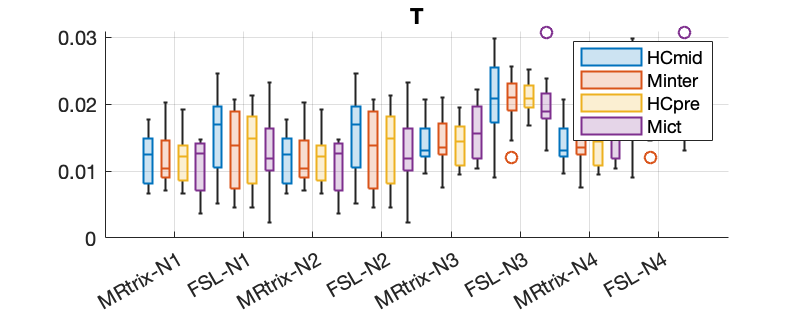

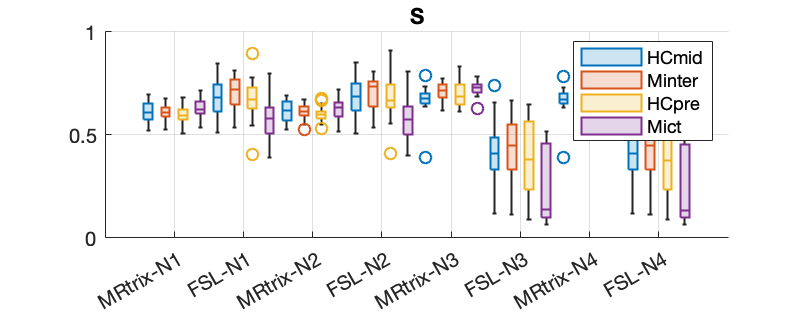

notlog=[3 4 6 7];

for metric=1:7
    clear data;i=1;
    for norm=1:length(normalizations)
        metrics=allmetrics{norm};
        for c=1:n_conditions
            data{i,:}=metrics{c}(metric,:);
            i=i+1;
        end
    end
    data=data';
    positionaldata=[];
    colordata=[];
    groups_position=[1 1 2 2 1 1 2 2 3 3 4 4 3 3 4 4 5 5 6 6 5 5 6 6 7 7 8 8 7 7 8 8]; %algorithm and norm
    groups_color=[1 2 1 2 3 4 3 4 1 2 1 2 3 4 3 4 1 2 1 2 3 4 3 4 1 2 1 2 3 4 3 4]; %conditions

    for i=1:length(data)
        positionaldata=[positionaldata groups_position(i)*ones(1,length(data{i}))];
        colordata=[colordata groups_color(i)*ones(1,length(data{i}))];

    end

    data=cell2mat(data);
    colorlabels={'HCmid' 'Minter' 'HCpre' 'Mict'};
    xlabels={'MRtrix-N1' 'FSL-N1' ...
        'MRtrix-N2' 'FSL-N2' ...
        'MRtrix-N3' 'FSL-N3'...
        'MRtrix-N4' 'FSL-N4'};
    positionaldata=discretize(positionaldata,1:9,'categorical',xlabels);

    figure('color','w','units','normalized','Position',[0.2,0.2,0.8,0.5])
    boxchart(positionaldata,data,'GroupByColor',colordata);
    if ~ismember(metric,notlog)
        set(gca, 'YScale', 'log');
    end
    grid on
    legend(colorlabels)
    title(metrics_labels(metric),'interpreter', 'none')
end


clear notlog positionaldata xlabels colorlabels data colordata groups_color groups_position i c metric norm
